% location = "./"
% directory = dir(location)
% disp(directory)

% NOTE:
% For file loading to work correctly,
% the "Current Folder" chosen on left hand side must be located at root
% location of directory

% location = ".\Project2\Images\train_images\Set1\";
location = ".\Project2\Images\train_images\Set1\";
img1 = imread(location + "1.jpg");
img2 = imread(location + "2.jpg");

directory = dir(location + '*.jpg')

directory = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


num_images=size(directory,1)

num_images = 3


for i=1:num_images
    curr_path = directory(i);
    folderchar = curr_path.folder;
    folder = convertCharsToStrings(folderchar) + "\"
    filechar = curr_path.name;
    file = convertCharsToStrings(filechar)
    path = folder + file
end

folder = "C:\Users\charm\Downloads\CMSC426_group\Project2\Images\train_images\Set1\"

file = "1.jpg"

path = "C:\Users\charm\Downloads\CMSC426_group\Project2\Images\train_images\Set1\1.jpg"

folder = "C:\Users\charm\Downloads\CMSC426_group\Project2\Images\train_images\Set1\"

file = "2.jpg"

path = "C:\Users\charm\Downloads\CMSC426_group\Project2\Images\train_images\Set1\2.jpg"

folder = "C:\Users\charm\Downloads\CMSC426_group\Project2\Images\train_images\Set1\"

file = "3.jpg"

path = "C:\Users\charm\Downloads\CMSC426_group\Project2\Images\train_images\Set1\3.jpg"

    
% grayscale
gray1 = rgb2gray(img1);
gray2 = rgb2gray(img2);

corners1 = cornermetric(gray1);
corners2 = cornermetric(gray2);

% imregional 
max1 = imregionalmax(corners1);
max2 = imregionalmax(corners2);

n_best = 500; 
%      [curr_img_x_best, curr_img_y_best] = ANMS(n_best, curr_img, curr_img_corners, curr_img_maxes)
%      [next_img_x_best, next_img_y_best] = ANMS(n_best, next_img, next_img_corners, next_img_maxes)

[X1, Y1] = ANMS(n_best, gray1, corners1, max1)

X1 =    450   195   419   222   417   152   199   297   299    73   289   447    53   151    33    55   167   284   178    29   180   105   347   417   330   417   300   297   299   104   364    41   400    39   359   330     8   235    25   228   161   350    57   136   447   410   259   366   262    40


Y1 =     33   503   282    18   427   289   151   395   232   143   576   594   362   363   465   289   431    50   570   552   209   448   586   369    10   228   286   449   179   216   494   416   590   600   432   118   192   124   257   531    64   541   185    32   536    37   449   107   204   224


[X2, Y2] = ANMS(n_best, gray2, corners2, max2)

X2 =    191   399   188   261   432    72    71   450   448    60   403   231   282   282   250     3    59     4   348   407    72   190   190   163   137   449   232   450   168   105   137   281   444   405   129    15   227   228   401   407    33   271   293    34   325    33    33    15   450   142


Y2 =    414   462   221    61   237   388   223   131     1    37   361   564   346   180   475   111   570   530    37   599   498   358   275    42    99   281    25   552   582   582   414   259   373   543   530   583    84   373   263   409   248    17   392   445   254   139   193    33   169     3


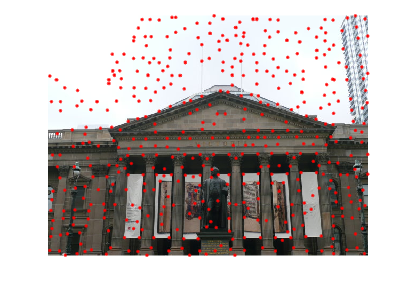



displayANMS(img1, Y1, X1);

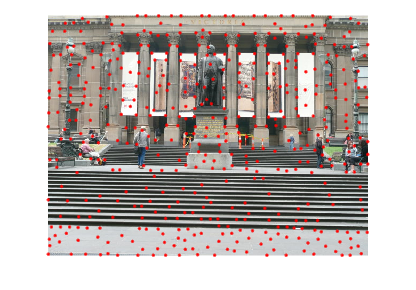

displayANMS(img2, Y2, X2);

%        displayANMS(curr_img, curr_img_y_best, curr_img_x_best);
%        displayANMS(next_img, next_img_y_best, next_img_x_best);

[d1, filteredX1, filteredY1] = feature_descriptors(gray1, X1, Y1)

d1 =     1.0263    0.8849    0.1627    1.0925    0.9464   -1.0464   -1.1552    0.8864   -0.0372    0.6776   -0.1343   -1.1588    0.9688    0.8883    0.3725    0.7281    0.6092    0.9310    0.6952    0.0285   -0.2289   -1.0814   -1.0676   -1.1021    1.5173   -2.1111   -1.2210   -0.0176    1.2493    0.8170    0.8178   -0.6074   -0.1927    0.0829    2.0486    0.5179    1.3682    1.1534    1.0021    1.5167    0.6511    1.4813   -2.0801   -0.8131    0.2125    1.0826    1.4499    1.5078    1.9046    0.6607
    1.0154    0.8849    0.1627    1.0925    0.9353   -1.0283   -1.1742    0.8864   -0.0372    0.6776    0.7171   -1.1588    0.7266    0.9008   -0.0922    0.7033    0.6092    0.9310    0.6952    0.1088   -0.3331   -1.1001   -1.0326   -1.1021    1.5173   -1.9494   -1.2210   -0.0713    1.0504    1.5108    0.8178   -0.1780   -0.1927    0.0239    2.0486   -0.3320    1.3273    0.5555    0.8948    0.2976    0.6511    0.2539   -1.4908    0.0542    0.2125    1.3237    1.9347   -1.0490   -0.8333    

filteredX1 =    503   282   427   289   151   395   232   143   576   362   363   465   289   431    50   570   552   209   448   369   228   286   449   179   216   494   416   432   118   124   257   531    64   541   185    32    37   449   107   204   224   504   318   468   362   114    52   267   338   289


filteredY1 =    195   419   417   152   199   297   299    73   289    53   151    33    55   167   284   178    29   180   105   417   417   300   297   299   104   364    41   359   330   235    25   228   161   350    57   136   410   259   366   262    40   259   185    72    86   404   324   231   230    86


[d2, filteredX2, filteredY2] = feature_descriptors(gray2, X2, Y2)

d2 =     0.8309    0.6324    0.5964   -1.1235   -1.0781   -1.3016   -0.2984   -1.4044    0.1222    0.4365   -1.1574    0.5668    0.1446   -0.9029   -1.0334    0.5357    1.0261    0.0010    1.0374    0.8927    0.2571   -0.9572   -1.3780    0.6911    0.0225   -0.3480   -1.4303    0.1945    1.2588    0.4482    1.1462    1.3029    1.0572    1.4507    1.1482    1.4571    0.5316   -1.4339    0.4534    0.7188   -0.9761    0.9568    0.1570   -1.3332   -1.7595    0.8597   -1.4297   -0.7859   -0.8603    0.9978
    0.6548   -1.5930    0.3975   -1.1905   -1.0367   -1.3876    0.8055    0.6068   -0.5907    0.6771    0.3241   -0.5442    0.2989    1.4625   -1.2030    0.5653    1.0411    0.4513    0.9184    0.9272    0.3494   -1.1840    0.6278    0.6911    0.4158    1.4347    0.6836   -1.6074    0.2989   -1.0187    0.3414   -0.6712    0.0309    0.1880    2.2308    0.2342    0.6012    0.7194    0.0763    0.6992    0.6054   -0.3230   -1.0229   -1.3754   -1.8031    0.5179    0.8166    0.6547   -0.6733    

filteredX2 =    414   462   221    61   388   223    37   361   564   346   180   475   570    37   498   358   275    42    99    25   414   259   543   530    84   373   263   409   248   392   445   254   139   193   404   500   104   172   260   525    43   538   135   177   331   560    98   465   466   334


filteredY2 =    191   399   188   261    72    71    60   403   231   282   282   250    59   348    72   190   190   163   137   232   137   281   405   129   227   228   401   407    33   293    34   325    33    33   250    35    52   400   222   235    93    55   290   216   175   294   399   289   139    37


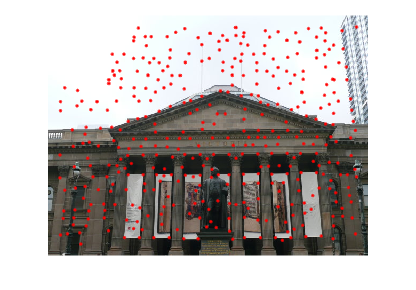



disp("")
displayANMS(img1, filteredX1, filteredY1);

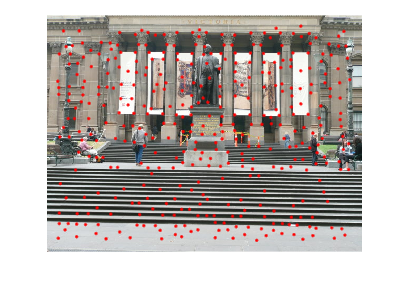

displayANMS(img2, filteredX2, filteredY2);

% matching points
match_threshold = 0.45;
[matchedp1X, matchedp1Y, matchedp2X, matchedp2Y] = getMatchedPoints(match_threshold, ...
    d1, d2, filteredX1, filteredY1, filteredX2, filteredY2)

matchedp1X =    232
   107
   226
   341
   513
   456
   368
   369
   399
   509


matchedp1Y =    299
   366
   340
   405
   414
   417
   351
   379
   417
   324


matchedp2X =    223
    99
   217
   331
   498
   443
   359
   359
   387
   501


matchedp2Y =     71
   137
   113
   175
   189
   191
   126
   154
   190
   101


% matched lines 

hprevImage = showMatchedFeatures(img1, img2, [matchedp1X, matchedp1Y], [matchedp2X, matchedp2Y], 'montage')

hprevImage =   Image with properties:

           CData: [450×1200×3 uint8]
    CDataMapping: 'direct'

  Show all properties


disp("")

% RANSAC
N_max = 1000000

N_max = 1000000

RANSAC_thresh = 1.4910

RANSAC_thresh = 1.4910


% N_max = 1000
RANSAC_thresh = 10

RANSAC_thresh = 10


[H_ls, INLIERSp1X, INLIERSp1Y, INLIERSp2X, INLIERSp2Y] = RANSAC(N_max, RANSAC_thresh, ...
    matchedp1X, matchedp1Y, matchedp2X, matchedp2Y);

iter: 0, ssd: 1.448564, percentage: 0.018868
iter: 0, ssd: 9.456507, percentage: 0.037736
iter: 0, ssd: 7.172026, percentage: 0.056604
iter: 0, ssd: 2.523108, percentage: 0.056604
iter: 0, ssd: 3.996028, percentage: 0.056604
iter: 0, ssd: 2.629640, percentage: 0.056604
iter: 0, ssd: 6.956253, percentage: 0.075472
iter: 0, ssd: 0.340212, percentage: 0.075472
iter: 0, ssd: 7.738460, percentage: 0.094340
iter: 0, ssd: 5.940693, percentage: 0.113208
iter: 0, ssd: 0.891509, percentage: 0.113208
iter: 0, ssd: 3.403681, percentage: 0.132075
iter: 0, ssd: 1.448564, percentage: 0.132075
iter: 0, ssd: 5.060028, percentage: 0.132075
iter: 0, ssd: 0.891509, percentage: 0.132075
iter: 0, ssd: 8.909730, percentage: 0.150943
iter: 0, ssd: 6.956253, percentage: 0.150943
iter: 0, ssd: 2.866798, percentage: 0.150943
iter: 0, ssd: 5.060028, percentage: 0.150943
iter: 0, ssd: 1.491953, percentage: 0.169811
iter: 0, ssd: 5.060028, percentage: 0.169811
iter: 0, ssd: 6.956253, percentage: 0.169811
iter: 0, s


hImage = showMatchedFeatures(img1, img2, [INLIERSp1X, INLIERSp1Y], [INLIERSp2X, INLIERSp2Y], 'montage')
disp("")

function [descriptors, X, Y] = feature_descriptors(img_grayscale, x, y)
    [~, n_best] = size(x);
    [ x_size, y_size] = size(img_grayscale);
    descriptors = []; X = []; Y = [];
    for i = 1:n_best
        % Patch is of size 41x41, so point is the actual center
        x_i = x(i);
        y_i = y(i);

        if (((x_i-19) >= 1) &&  ((y_i-19)>=1) && ((x_i + 20) <= x_size) && ((y_i + 20) <= y_size))
            
            patch = img_grayscale(x_i-19:x_i+20, y_i-19:y_i+20);
            sig = 0.1;
            blurred = imgaussfilt(patch, sig);
%             imshow(patch)
%             figure(10,10); imshow(blurred)

%             resized = imresize(blurred, [8 8]);
            resized = blurred(1:5:end, 1:5:end);
            
            reshaped = double(reshape(resized, [64, 1]));
            
            std_dev = std(reshaped);
            mean_reshaped = mean(reshaped);
            standardized = (reshaped - mean_reshaped) ./ std_dev;
            descriptors = [descriptors standardized];
            X = [X y_i];
            Y = [Y x_i];
            disp("")
        end
    end
    disp("")
end

function [matchedp1X, matchedp1Y, matchedp2X, matchedp2Y] = getMatchedPoints(thresh, d1, d2, p1X, p1Y, p2X, p2Y)
    matchedp1X = [];matchedp1Y = [];matchedp2X = [];matchedp2Y = [];
    d1size = length(d1(1,:));d2size = length(d2(2,:));

    for i = 1:d1size
        sumSquare = zeros(1,d2size);
        for j = 1:d2size
            sumSquare(j) = sum((d1(:,i) - d2(:,j)).^2);
        end
        [sortedDist, I] = sort(sumSquare);
        ratio = sortedDist(1)/sortedDist(2);
        if (ratio < thresh)
            matchedp1X = [matchedp1X; p1X(i)];
            matchedp1Y = [matchedp1Y; p1Y(i)];

            matchedp2X = [matchedp2X; p2X(I(1))];
            matchedp2Y = [matchedp2Y; p2Y(I(1))];
        end
    end
end

function [x_best, y_best] = ANMS(n_best, gray_img, corners, maxima)
    
    NStrong = 0;
    [sizeX, sizeY] = size(gray_img);
    x = []; y = [];

    for x_i = 1:sizeX
        for y_i = 1:sizeY
            if maxima(x_i,y_i) == 1
                NStrong = NStrong + 1;
                x = [x x_i];
                y = [y y_i]; 
            end
        end
    end
    
    r = Inf(1, NStrong);
    for i = 1:NStrong
        for j = 1:NStrong
%             if img_corners(y(j), x(j)) > img_corners(y(i), x(i))
            if corners(x(j), y(j)) > corners(x(i), y(i))
                ED = ((x(j) - x(i))^2) + ((y(j) - y(i))^2);
                if ED < r(i)
                    r(i) = ED;
                end
            end
        end
    end
    
    x_best = zeros(1, n_best);
    y_best = zeros(1, n_best);    
    [~, I] = sort(r, 'descend');
    
    for i = 1:n_best
        x_best(i) = x(I(i));
        y_best(i) = y(I(i));
    end
end

function displayANMS(img, x_best, y_best)
    figure
    imshow(img)
    hold on
%      plot(x_best, y_best, 'Color', 'r', 'Marker','.', 'LineStyle','-')
    plot(x_best, y_best, 'r.')
    hold off
end

function H = est_homography(X,Y,x,y)
    % H = est_homography(X,Y,x,y)
    % Compute the homography matrix from source(x,y) to destination(X,Y)
    %
    %    X,Y are coordinates of destination points
    %    x,y are coordinates of source points
    %    X/Y/x/y , each is a vector of n*1, n>= 4
    %
    %    H is the homography output 3x3
    %   (X,Y, 1)^T ~ H (x, y, 1)^T
    
    A = zeros(length(x(:))*2,9);
    
    for i = 1:length(x(:))
     a = [x(i),y(i),1];
     b = [0 0 0];
     c = [X(i);Y(i)];
     d = -c*a;
     A((i-1)*2+1:(i-1)*2+2,1:9) = [[a b;b a] d];
    end
    
    [U S V] = svd(A);
    h = V(:,9);
    H = reshape(h,3,3)';
end

function [X, Y] = apply_homography(H, x, y)
    % [X, Y] = apply_homography(H, x, y)
    % Use homogrphay matrix H to compute position (x,y) in the source image to
    % the position (X,Y) in the destination image
    %
    % Input
    %   H : 3*3 homography matrix, refer to setup_homography
    %   x : the column coords vector, n*1, in the source image
    %   y : the column coords vector, n*1, in the source image
    % Output
    %   X : the column coords vector, n*1, in the destination image
    %   Y : the column coords vector, n*1, in the destination image
    
    p1 = [x'; y'; ones(1, length(x))];
    q1 = H*p1;
    q1 = q1./[q1(3, :); q1(3,:); q1(3, :)];
    
    X = q1(1,:)';
    Y = q1(2, :)';
end

function [H_ls, INLIERSp1X, INLIERSp1Y, INLIERSp2X, INLIERSp2Y] = RANSAC(N_max, thresh, match1X, match1Y, match2X, match2Y)
    
    total = size(match1X, 1); inliers_count = 0; iter = 0;
    INLIERSXY = [];
    ssds = [];
    
    while (iter < N_max && ((inliers_count/total) < 0.90))

%         random_i = randi([1 total], 1, 4);
        random_i = randperm(total, 4);

        % 1. Select four pairs of matched pixels (at random), 1<=i<=4, p_1i/p_2i from images 1/2.
        tempX1 = match1X(random_i); tempY1 = match1Y(random_i);
        tempX2 = match2X(random_i); tempY2 = match2Y(random_i);
        
        if (ismember(346,tempX1) || ismember(312,tempX1) || ismember(407,tempX1))
            disp("")
        end
        
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 2. Compute the homography matrix from the four feature pairs using est_homography
        H = est_homography(tempX1,tempY1,tempX2,tempY2);
        
        % 3. Compute inliers where SSD(Hp_1, p_2) < threshold
        for i=1:4

            p2 = [tempX2(i); tempY2(i)];
            [Hp1X, Hp1Y] = apply_homography(H, [tempX1(i)], [tempY1(i)]);
            Hp1 = [Hp1X; Hp1Y];            
            
%             p2 = [tempX2(i); tempY2(i); 1];
%             p1 = [tempX1(i); tempY1(i); 1];
%             Hp1 = H*p1;
            
            X = Hp1 - p2;
            ssd = sum(X(:).^2);
            
            if (tempX1(i) == 346 || tempX1(i)==312 || tempX1(i)==407 ...
                        || tempX1(i)==184 || tempX1(i)==202)
                disp("")
            end
            
%             ssds = [ssds ssd];
            if (ssd < thresh)
                if (tempX1(i) == 346 || tempX1(i)==312 || tempX1(i)==407 ...
                        || tempX1(i)==184 || tempX1(i)==202)
                    disp("")
                end
                INLIERSXY = [INLIERSXY; [tempX1(i), tempY1(i), tempX2(i), tempY2(i)]];
                INLIERSXY = unique(INLIERSXY, 'rows', 'stable');
                inliers_count = size(INLIERSXY,1);
                fprintf("iter: %d, ssd: %f, percentage: %f\n", iter, ssd, (inliers_count/total))
            end
        end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         % 2. Compute the homography matrix from the four feature pairs using est_homography
%         H = est_homography(tempX1,tempY1,tempX2,tempY2);
%         
%         % 3. Compute inliers where SSD(Hp_1, p_2) < threshold
% 
%         p2 = [tempX2, tempY2];
%         [Hp1X, Hp1Y] = apply_homography(H, tempX1, tempY1);
%         Hp1 = [Hp1X, Hp1Y];
%         X = Hp1 - p2;
%         ssd = sum(X(:).^2);
%         
% %         if (ismember(346,tempX1) || ismember(312,tempX1) || ismember(407,tempX1))
% %             ssd
% %             disp("")
% %         end
%         
%         if (ssd < thresh)
%             if (ismember(346,tempX1) || ismember(312,tempX1) || ismember(407,tempX1))
%                 ssd
%                 disp("")
%             end
%             for i=1:4
%                 INLIERSXY = [INLIERSXY; [tempX1(i), tempY1(i), tempX2(i), tempY2(i)]];
%                 INLIERSXY = unique(INLIERSXY, 'rows', 'stable');
%                 inliers_count = size(INLIERSXY,1);
%             end
%             fprintf("iter: %d, ssd: %f, percentage: %f\n", iter, ssd, (inliers_count/total))
%         end
%         
%         % 4. Repeat the last 3 steps until you reach N_max iters or 90% of inliers.
%         iter = iter + 1;
%         % 5. Keep largest set of inliers.
%     end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
    ssds
    % 6. Recompute least-square H on all inliers.    
    H_ls = est_homography(INLIERSXY(:,1),INLIERSXY(:,2),INLIERSXY(:,3),INLIERSXY(:,4))
    
    INLIERSp1X = INLIERSXY(:,1)
    INLIERSp1Y = INLIERSXY(:,2)
    INLIERSp2X = INLIERSXY(:,3)
    INLIERSp2Y = INLIERSXY(:,4)

    iter
    
    fprintf("end RANSAC");
end

function hImage = showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, varargin)
%showMatchedFeatures Display corresponding feature points.
%  showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2) displays a
%  falsecolor overlay of images I1 and I2, with a color-coded plot of the
%  corresponding points connected by a line. matchedPoints1 and
%  matchedPoints2 are the coordinates of corresponding points in I1 and
%  I2. Points can be an M-by-2 matrix of [x y] coordinates, a SURFPoints
%  an MSERRegions, a cornerPoints, or a BRISKPoints object.
%
%  showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, method)
%  displays images I1 and I2 using the visualization style specified by
%  method. Values of method can be:
%
%    'falsecolor' : Overlay the images by creating a composite red-cyan 
%                   image showing I1 as red and I2 as cyan.
%    'blend'      : Overlay I1 and I2 using alpha blending.
%    'montage'    : Place I1 and I2 next to each other in the same image.
%
%    Default: 'falsecolor'
%
%  hImage = showMatchedFeatures(...) returns the handle to the image object
%  returned by showMatchedFeatures.
%
%  showMatchedFeatures(...,Name,Value) specifies additional name-value pair 
%  arguments described below:
%
%  'PlotOptions'  Specify custom plot options in a cell array containing 
%                 three string values, {MarkerStyle1, MarkerStyle2, LineStyle},
%                 corresponding to marker specification in I1, marker 
%                 specification in I2, and line style and color. Each of 
%                 the specifiers is defined by the LineSpec of PLOT function.
%
%                 Default: {'ro','g+','y-'}
%
%   'Parent'      Specify an output axes for displaying the visualization.
%
%  Class Support
%  -------------
%  I1 and I2 are numeric arrays.
%
%  Example 1
%  ---------
%  % Use Harris features to find corresponding points between two images.
%  I1 = rgb2gray(imread('parkinglot_left.png'));
%  I2 = rgb2gray(imread('parkinglot_right.png'));
%
%  points1 = detectHarrisFeatures(I1);
%  points2 = detectHarrisFeatures(I2);
%   
%  [f1, vpts1] = extractFeatures(I1, points1);
%  [f2, vpts2] = extractFeatures(I2, points2);
%
%  indexPairs = matchFeatures(f1, f2) ;
%  matchedPoints1 = vpts1(indexPairs(1:20, 1));
%  matchedPoints2 = vpts2(indexPairs(1:20, 2));
%
%  % Visualize putative matches
%  figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,'montage');
%
%  title('Putative point matches');
%  legend('matchedPts1','matchedPts2');
%
%  Example 2
%  ---------
%  % Use SURF features to find corresponding points between two images
%  % rotated and scaled with respect to each other
%  I1 = imread('cameraman.tif');
%  I2 = imresize(imrotate(I1,-20), 1.2);
% 
%  points1 = detectSURFFeatures(I1);
%  points2 = detectSURFFeatures(I2);
% 
%  [f1, vpts1] = extractFeatures(I1, points1);
%  [f2, vpts2] = extractFeatures(I2, points2);
%         
%  indexPairs = matchFeatures(f1, f2) ;
%  matchedPoints1 = vpts1(indexPairs(:, 1));
%  matchedPoints2 = vpts2(indexPairs(:, 2));
%
%  % Visualize putative matches
%  figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2);
%
%  title('Putative point matches');
%  legend('matchedPts1','matchedPts2');
%
% See also matchFeatures, estimateGeometricTransform, imshowpair,
%     legend, SURFPoints, MSERRegions, cornerPoints

% Copyright 2011 The MathWorks, Inc.

narginchk(4,7);
 
[matchedPoints1, matchedPoints2, method, lineSpec, hAxes] = ...
    parseInputs(I1, I2, matchedPoints1, matchedPoints2, varargin{:});

% pad the smaller image
paddedSize = [max(size(I1,1), size(I2,1)), max(size(I1,2), size(I2,2))];
I1pad = [paddedSize(1) - size(I1,1), paddedSize(2) - size(I1,2)];
I2pad = [paddedSize(1) - size(I2,1), paddedSize(2) - size(I2,2)];
I1pre = round(I1pad/2);
I2pre = round(I2pad/2);
I1 = padarray(I1, I1pre, 0, 'pre');
I2 = padarray(I2, I2pre, 0, 'pre');
I1 = padarray(I1, I1pad-I1pre, 0, 'post');
I2 = padarray(I2, I2pad-I2pre, 0, 'post');

switch lower(method)
    case {'falsecolor'}
        imgOverlay = imfuse(I1, I2);
        % create red-cyan image instead of the imfuse default
        imgOverlay(:,:,1) = imgOverlay(:,:,2);
        imgOverlay(:,:,2) = imgOverlay(:,:,3);
    case {'blend'}
        imgOverlay = imfuse(I1,I2,'blend');        
    case {'montage'}
        imgOverlay = imfuse(I1,I2,'montage');
end

% Display the composite image
if nargout > 0
    hImage = imshow(imgOverlay, 'Parent', hAxes);
else
    imshow(imgOverlay, 'Parent', hAxes);
end

holdState = get(hAxes,'NextPlot'); % store the state for 'hold' before changing it
set(hAxes, 'NextPlot', 'add');

%============
% Plot points
%============
% Calculate the offsets needed to adjust plot after images were fused
offset1 = fliplr(I1pre);
offset2 = fliplr(I2pre);
if strcmp(method, 'montage')
    offset2 = offset2 + fliplr([0 size(I1,2)]);
end

matchedPoints1 = bsxfun(@plus, matchedPoints1, offset1);
matchedPoints2 = bsxfun(@plus, matchedPoints2, offset2);

if ~isempty(lineSpec{1})
    plot(hAxes, matchedPoints1(:,1), matchedPoints1(:,2), lineSpec{1}); % marker 1
end
if ~isempty(lineSpec{2})
    plot(hAxes, matchedPoints2(:,1), matchedPoints2(:,2), lineSpec{2}); % marker 2
end

% Plot by using a single line object with line segments broken by using
% NaNs. This is more efficient and makes it easier to customize the lines.
lineX = [matchedPoints1(:,1)'; matchedPoints2(:,1)'];
numPts = numel(lineX);
lineX = [lineX; NaN(1,numPts/2)];

lineY = [matchedPoints1(:,2)'; matchedPoints2(:,2)'];
lineY = [lineY; NaN(1,numPts/2)];

plot(hAxes, lineX(:), lineY(:), lineSpec{3}); % line

set(hAxes, 'NextPlot', holdState); % restore the hold state

drawnow();
end

%==========================================================================
% Input parser
%==========================================================================
function [matchedPoints1, matchedPoints2, method, lineSpec, hAxes] = ...
    parseInputs(I1, I2, matchedPoints1, matchedPoints2, varargin)

% do only basic image validation; let padarray and imfuse take care of 
% the rest
validateattributes(I1,{'numeric','logical'},{'real','nonsparse',...
    'nonempty'},mfilename,'I1',1)
validateattributes(I2,{'numeric','logical'},{'real','nonsparse',...
    'nonempty'},mfilename,'I2',2)

matchedPoints1 = parsePoints(matchedPoints1, 1);
matchedPoints2 = parsePoints(matchedPoints2, 2);

if size(matchedPoints1,1) ~= size(matchedPoints2,1)
    error(message('vision:showMatchedFeatures:numPtsMustMatch'));
end

% Process the rest of inputs
parser = inputParser;
parser.FunctionName  = mfilename;

parser.addOptional('Method', 'falsecolor', @checkMethod);
parser.addParameter('PlotOptions', {'ro','g+','y-'}, @checkPlotOptions);
parser.addParameter('Parent', [], ...
    @vision.internal.inputValidation.validateAxesHandle);

% Parse inputs
parser.parse(varargin{:});

% Calling validatestring again permits easy handling of partial string matches
method = validatestring(parser.Results.Method,...
    {'falsecolor','blend','montage'},mfilename,'Method');

lineSpec = parser.Results.PlotOptions;

hAxes = newplot(parser.Results.Parent);
end

%==========================================================================
function points=parsePoints(points, ptsInputNumber)

fcnInputVarNumber = 2 + ptsInputNumber; 
varName = ['matchedPoints', num2str(ptsInputNumber)];

if ~isa(points, 'vision.internal.FeaturePoints') && ~isa(points, 'MSERRegions')
    validateattributes(points,{'int16', 'uint16', 'int32', 'uint32', ...
        'single', 'double'}, {'2d', 'nonsparse', 'real', 'size', [NaN 2]},...
        mfilename, varName, fcnInputVarNumber);
else
    points = points.Location;
end

points = double(points);
end

%==========================================================================
function tf = checkMethod(method)

validatestring(method,{'falsecolor','blend','montage'},mfilename,'Method');

tf = true;
end

%==========================================================================
function tf = checkPlotOptions(options)

validateattributes(options,{'cell'}, {'size', [1 3]},...
    mfilename, 'PlotOptions');

validateattributes(options{1},{'char'},{},mfilename,'MarkerStyle1');
validateattributes(options{2},{'char'},{},mfilename,'MarkerStyle2');
validateattributes(options{3},{'char'},{},mfilename,'LineStyle');

% Now check valid strings
checkMarkerStyle(options{1}, 1);
checkMarkerStyle(options{2}, 2);

checkLineStyle(options{3});

tf = true;
end
%==========================================================================
function style=eliminateColorSpec(style)

colorSpec = cell2mat({'r','g','b','c','m','y','k','w'});

% Color can be specified only at the beginning or end of the style string.
% Look for only one specifier. If color was specified twice, it will cause
% a failure in later stages of parsing
if ~isempty(style)
    if isempty(strfind(colorSpec, style(1)))
        % try the other end
        if ~isempty(strfind(colorSpec, style(end)))
            style(end) = [];
        end
    else
        style(1) = [];
    end
end
end
%==========================================================================
function checkMarkerStyle(style, id)

style = strtrim(style); % remove blanks from either end of the string
style = strtrim(eliminateColorSpec(style)); % pull out valid color spec

if isempty(style)
   % permit empty marker style, which amounts to marker not being displayed 
else
    markerSpec = {'+','o','*','.','x','square','s','diamond','d','^',...
        'v','>','<','pentagram','p','hexagram','hImage'};
    
    try
        validatestring(style,markerSpec);
    catch %#ok<CTCH>
        error(message('vision:showMatchedFeatures:invalidMarkerStyle',id));
    end
end
end
%==========================================================================
function checkLineStyle(style)

style = strtrim(style); % remove blanks from either end of the string
style = strtrim(eliminateColorSpec(style)); % pull out valid color spec

if isempty(style)
    % permit empty line style thus letting plot use its default settings
else
    lineSpec = {'-','--',':','-.'};
    
    try
        validatestring(style,lineSpec);
    catch %#ok<CTCH>
        error(message('vision:showMatchedFeatures:invalidLineStyle'));
    end
end
end
